## **HW5  Q3  - ADI method**

### define constants:

clear;clc
dt=0.01/12; dx=0.1; dy=dx; k=2;
lambda=k*dt/dx^2

lambda = 0.1667

L=2; % plat length
t_end = 0.5;
len_x = L/dx+1;
len_y = L/dy+1;
len_t = round(t_end/dt)*2+1; % t is now define twice the size because of the half steps.

T is the solutions matrix (including half-steps that will be remove at the end)

T = zeros(len_x ,len_y ,len_t);

### define initial conditions in T

T(:,:,1)=0;

x = [0:dx:L];
for t_idx = 1:len_t
    T(:,1,t_idx)= x.*(2-x);  
end

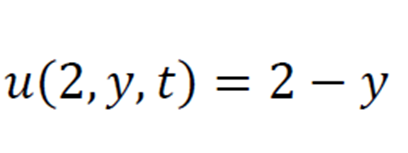

y = [0:dy:L]';
for t_idx = 1:len_t
    T(end,:,t_idx)= (2-y);  
end

T(:,end,:) = 1;

    Define A for vector solving  

A =              

A=zeros((L/dx-1)); % dx = dy and that why we can use one definition for A
A(1:(L/dx-1)+1:end)=2*(1+lambda);
A(2:(L/dx-1)+1:end)=-lambda;
A((L/dx-1)+1:(L/dx-1)+1:end)=-lambda;

### Solving x and y when initial x explict

for l = 2:2:(len_t-1)

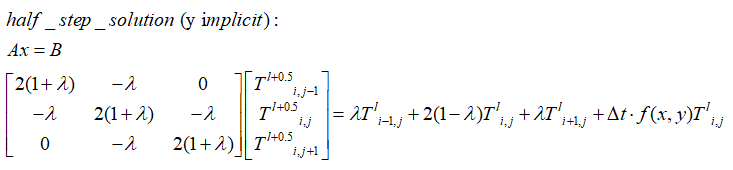

    for j = 2:(len_y-1)
        % Define B 
        B = lambda*T(1:end-2,j,l-1)+2*(1-lambda)*T(2:end-1,j,l-1)+lambda*T(3:end,j,l-1) + dt*f(x(2:end-1),y(j)).*T(2:end-1,j,l-1);        
        % Adding B.C. to B vector
        B(end) = B(end) + lambda*T(end,j,l);
        % Solve y_j 
        T(2:end-1,j,l)=(A\B);
    end    

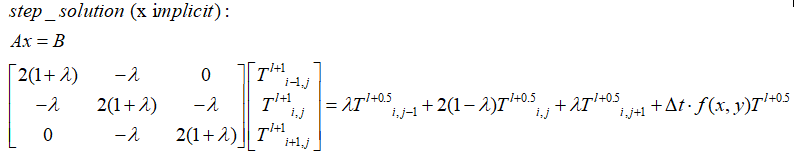

    for i = 2:(len_x-1)
        % Define B 
        B = lambda*T(i,1:end-2,l)+2*(1-lambda)*T(i,2:end-1,l)+lambda*T(i,3:end,l) + dt*f(x(i),y(2:end-1)).*T(i,2:end-1,l);
        % Adding B.C. to B vector
        B(1) = B(1)+lambda*T(i,1,l+1);
        B(end) = B(end)+lambda*T(end,1,l+1);
        % Solve x_i
        T(i,2:end-1,l+1)=(A\B')';
    end

    

    T(1,:,l+1)=T(2,:,l+1); 
end

Removing the half-steps from T

T = T(:,:,1:2:len_t);

Plotting the solution matrix

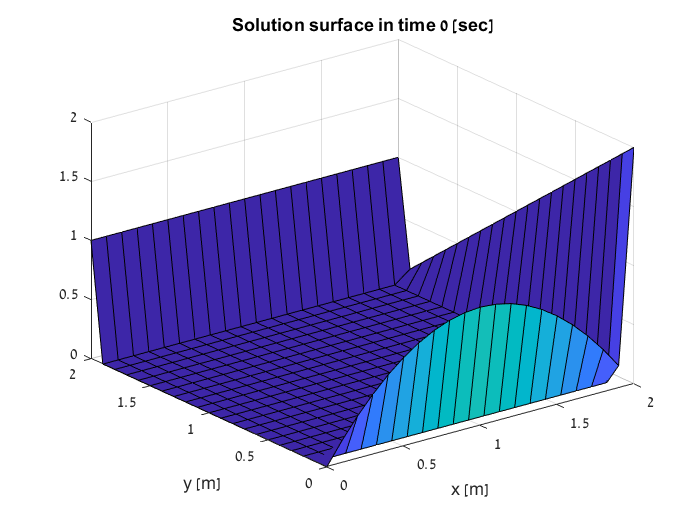

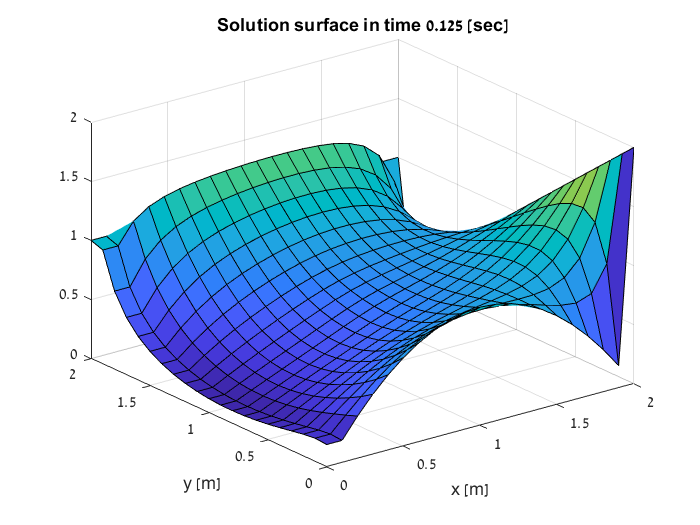

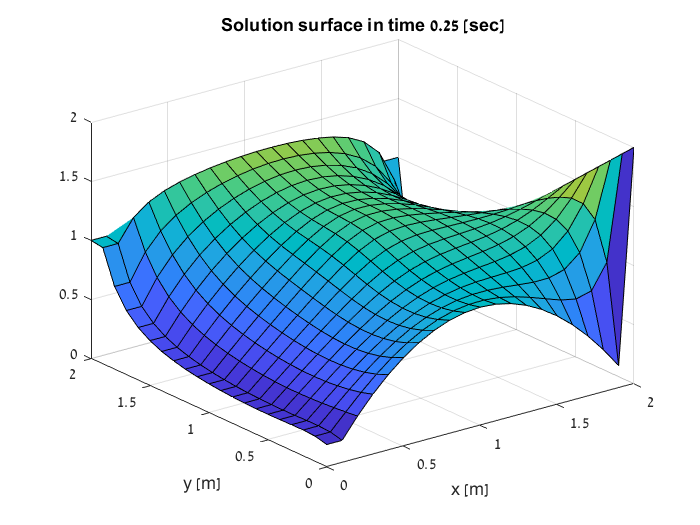

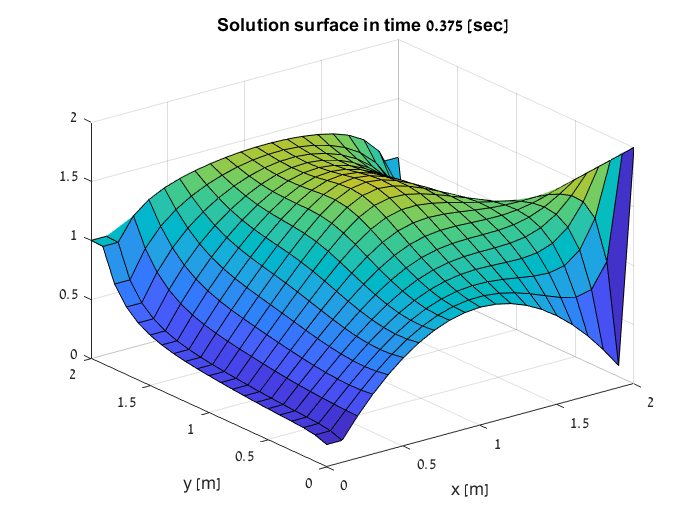

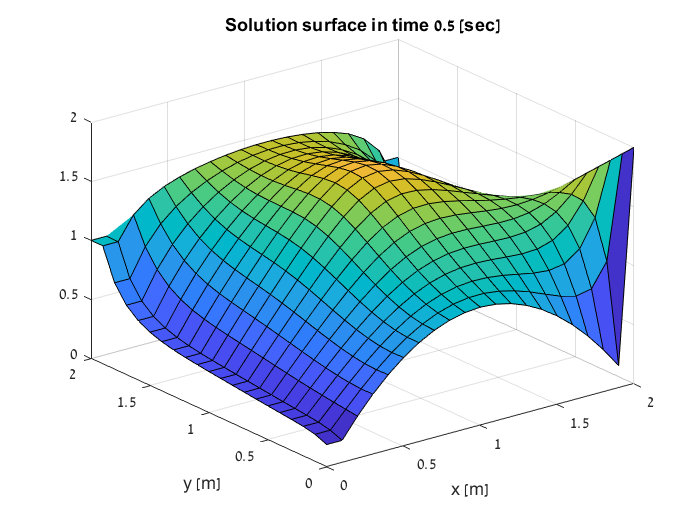

T_index = round(linspace(1,((len_t-1)/2+1),5));
t = [0:dt:t_end];
[X,Y] = meshgrid(x,y);
for t_idx = T_index
    figure
    surf(X,Y,T(:,:,t_idx)')
    xlabel ('x [m]'); ylabel ('y [m]');
    title (['Solution surface in time ',num2str(t(t_idx)) ,' [sec]'])
    
end

function fval = f(x,y)
fval = 1./((x-1).^2+(y-1).^2+0.1);
fval = reshape(fval,length(x),length(y));
end

